clear;
Model_scripts = {'_1Base','_2Base+AH','_2Base+H','_2Base+O','_2Base+T','_3Base+AH+H','_3Base+AH+O','_3Base+AH+T','_3Base+O+H','_3Base+T+H',...
    '_3Base+T+O','_4Base+AH+O+H','_4Base+AH+T+H','_4Base+AH+T+O','_4Base+T+O+H','_5Base+AH+T+O+H'};
address = Model_scripts;

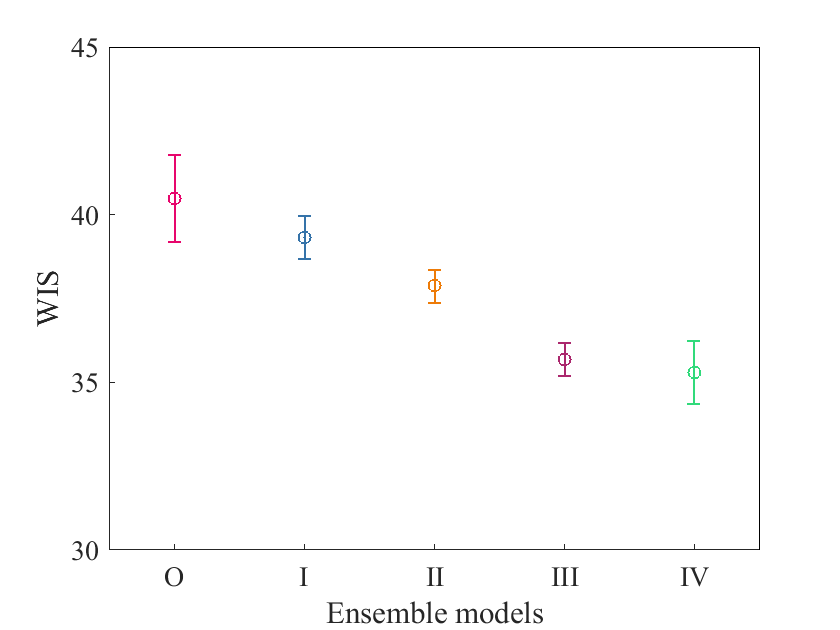

WIS_Short=[];WIS_Long=[];
for number = 1:numel(address)
      % cd ('F:\Dong\SPH Dropbox\Wang Dong\PC\Modelling_gLobally1')
    % cd('C:\Users\Dong\SPH Dropbox\Wang Dong\PC\_4_modeling_end_1')
    cd("E:\Dong\one_drive\OneDrive - The University Of Hong Kong\_4_modeling_end_log_normal")
     cd (address{number});
     load('cross_WIS.mat');WIS4=WIS4(1:8,1:7);
     WIS_Short(number,:,:) = WIS1;
     WIS_Long(number,:,:)  = WIS4;
     WIS11 = sort(WIS1(:));
     Mean_Short(number,:)  = mean(mean(WIS11(2:end-1)));
     WIS44 = sort(WIS4(:));
     Mean_Long(number,:)   = mean(mean(WIS44(2:end-1)));
     Mean_year_Short(number,:)  = mean(WIS1);
     Mean_year_Long(number,:)   = mean(WIS4);
end

model_number={[1],[2:5],[6:11],[12:15],[16]};
for i=1:5
  Ensemble_Short_mean (i)  = mean (Mean_Short(model_number{i}));
  Ensemble_Long_mean (i)  = mean (Mean_Long(model_number{i}));
  Ensemble_Short{i}=WIS_Short(model_number{i},:,:);
  Ensemble_Long{i}=WIS_Long(model_number{i},:,:);
end
colors =[0.906308150649733	0.0225125927402318	0.422885689100085
0.208934922426023	0.450137696965896	0.662009598359135
0.928313062314188	0.484296511212103	0.0319910157625669
0.669175304534394	0.156404952226563	0.428252992979386
0.190433267179954	0.855522805845911	0.482022061031856];
figure;hold on;
Number_values = [56,224,336,224,56];
for figs=1:5
    e1 = errorbar(figs,Ensemble_Long_mean(figs), std(Ensemble_Long{figs}(:))/sqrt(Number_values(figs)));set(e1,  'LineWidth', 1, 'Marker', 'o', 'MarkerSize', 6,'color',colors(figs,:))
end
xlim([0.5 5.5]);ylim([30 45]);set(gca,"XTick",[1:1:5],"xticklabel",{'O','I','II','III','IV'})
xlabel('Ensemble models');ylabel('WIS');set(gca,'FontName','Times New Roman','FontSize',14);
box_off
exportgraphics(gcf,'FigureS Long_WIS.pdf','ContentType','vector')

model_number={[1],[2:5],[6:11],[12:15],[16]};
EN_valuesshort_CF  = [8,32,48,32,8];
EN_valueslong_CF   = [7,28,42,28,7];
yearshort_CF       =[2012,2013,2014,2015,2016,2017,2018,2019];
yearlong_CF        =[2012,2013,2014,2015,2016,2017,2018];
Ranks_short_CF=[];Ranks_Long_CF=[];

EN_valuesshort_P = [8,32,48,32,8];% [5,20,30,20,5];
EN_valueslong_P  = [7,28,42,28,7];%[5,20,30,20,5];
yearshort_P      = [2016,2017,2018,2019,2020,2021,2022,2023];
yearlong_P       = [2016,2017,2018,2019,2020,2021,2022];
Ranks_short_P=[];Ranks_Long_P=[];

Weights_long_CF=[];Weights_short_CF=[];Weights_long_P=[];Weights_short_P=[];
for ENmodel = 1:4
Ranks_short_CF{ENmodel} = Mean_year_Short(model_number{ENmodel},:);
Ranks_Long_CF{ENmodel}  = Mean_year_Long(model_number{ENmodel},:);

Ranks_short_P{ENmodel} = Mean_year_Short(model_number{ENmodel},1:length(yearshort_P));
Ranks_Long_P{ENmodel}  = Mean_year_Long(model_number{ENmodel},1:length(yearlong_P));

[~,C1S_CF]=sort(Ranks_short_CF{ENmodel}(:));[~,F1S_CF]=sort(C1S_CF(:)); Ranks_short_CF{ENmodel}=reshape(F1S_CF,length(model_number{ENmodel}),8);
[~,C1S_P]=sort(Ranks_short_P{ENmodel}(:));[~,F1S_P]=sort(C1S_P(:)); Ranks_short_P{ENmodel}=reshape(F1S_P,length(model_number{ENmodel}),length(yearshort_P));
% Table1s = string(round(Ranks_short_CF{ENmodel},2));Table2s = string(Ranks_short_CF{ENmodel});
[~,C1L_CF]=sort(Ranks_Long_CF{ENmodel}(:));[~,F1L_CF]=sort(C1L_CF(:)); Ranks_Long_CF{ENmodel}=reshape(F1L_CF,length(model_number{ENmodel}),7);
[~,C1L_P]=sort(Ranks_Long_P{ENmodel}(:));[~,F1L_P]=sort(C1L_P(:)); Ranks_Long_P{ENmodel}=reshape(F1L_P,length(model_number{ENmodel}),length(yearlong_P));

% Table1L = string(round(Ranks_short_CF{ENmodel},2));Table2L = string(Ranks_Long_CF{ENmodel});

for col=1:length(yearshort_CF)
    for row=1:numel(Model_scripts(model_number{ENmodel}))
        Weights_short_CF{ENmodel}(row,col)= rank_order_centroid_weighting(EN_valuesshort_CF(ENmodel),Ranks_short_CF{ENmodel}(row,col));
    end
end
for col=1:length(yearlong_CF)
    for row=1:numel(Model_scripts(model_number{ENmodel}))
        Weights_long_CF{ENmodel}(row,col) = rank_order_centroid_weighting(EN_valueslong_CF(ENmodel),Ranks_Long_CF{ENmodel}(row,col));
    end
end
for col=1:length(yearshort_P)
    for row=1:numel(Model_scripts(model_number{ENmodel}))
        Weights_short_P{ENmodel}(row,col)= rank_order_centroid_weighting(EN_valuesshort_P(ENmodel),Ranks_short_P{ENmodel}(row,col));
    end
end
for col=1:length(yearlong_P)
    for row=1:numel(Model_scripts(model_number{ENmodel}))
        Weights_long_P{ENmodel}(row,col) = rank_order_centroid_weighting(EN_valueslong_P(ENmodel),Ranks_Long_P{ENmodel}(row,col));
    end
end
sum(sum(Weights_short_CF{ENmodel}))
sum(sum(Weights_long_CF{ENmodel}))
sum(sum(Weights_short_P{ENmodel}))
sum(sum(Weights_long_P{ENmodel}))
end

ans = 1

ans = 1

ans = 1

ans = 1

ans = 1

ans = 1

ans = 1

ans = 1

ans = 1

ans = 1

ans = 1

ans = 1

ans = 1

ans = 1

ans = 1

ans = 1

for ENmodel=1:4
N = 2000;
R_newPI_short{ENmodel}=zeros(N,8+52+7);R_newPI_Long{ENmodel}=zeros(N,53+52+7);R_newPI_shortCF{ENmodel}=zeros(N,8);R_newPI_LongCF{ENmodel}=zeros(N,53);
R_newPI_short1{ENmodel}=zeros(N,8+52);R_newPI_Long1{ENmodel}=zeros(N,8+52);R_newPI_shortCF1{ENmodel}=zeros(N,8);R_newPI_LongCF1{ENmodel}=zeros(N,8);
P_newPI_short{ENmodel}=zeros(N,8+52);P_newPI_Long{ENmodel}=zeros(N,52+52);
P_newPI_short1{ENmodel}=zeros(N,29);P_newPI_Long1{ENmodel}=zeros(N,29);
R_newPI_shortCF_F{ENmodel}=zeros(N,8);R_newPI_LongCF_F{ENmodel}=zeros(N,53);

for row=1:numel(Model_scripts(model_number{ENmodel}))
    % cd('F:\Dong\SPH Dropbox\Wang Dong\PC\Modelling_gLobally1')
    cd("E:\Dong\one_drive\OneDrive - The University Of Hong Kong\_4_modeling_end_log_normal")
    cd(Model_scripts{model_number{ENmodel}(row)});
    for col=1:length(yearshort_CF)
        load(sprintf('ABase_%d.mat',yearshort_CF(col)),'PIdata','PIdataCF','CIdata','CIdataCF');
        load(sprintf('PICF_Fore_ave_%d.mat',yearshort_CF(col)));
        if ENmodel == 1
            PIdataCF_Fore = PIdataCF;
        end
        R_newPI_short{ENmodel}   = R_newPI_short{ENmodel} + Weights_short_CF{ENmodel}(row,col).*PIdata(1:N,end-234-15+0-52-7:end-227-15+0);
        R_newPI_shortCF{ENmodel} = R_newPI_shortCF{ENmodel} + Weights_short_CF{ENmodel}(row,col).*PIdataCF(1:N,end-234-15+0:end-227-15+0);
        R_newPI_shortCF_F{ENmodel} = R_newPI_shortCF_F{ENmodel} + Weights_short_CF{ENmodel}(row,col).*PIdataCF_Fore(1:N,end-234-15+0:end-227-15+0);
    end
    for col=1:length(yearlong_CF)
        load(sprintf('ABase_%d.mat',yearlong_CF(col)),'PIdata','PIdataCF','CIdata','CIdataCF');
        load(sprintf('PICF_Fore_ave_%d.mat',yearshort_CF(col)));
        if ENmodel == 1
            PIdataCF_Fore = PIdataCF;
        end
        R_newPI_Long{ENmodel}    = R_newPI_Long{ENmodel} + Weights_long_CF{ENmodel}(row,col).*PIdata(1:N,end-234-15+0-52-7:end-182-15+0);
        R_newPI_LongCF{ENmodel}  = R_newPI_LongCF{ENmodel} + Weights_long_CF{ENmodel}(row,col).*PIdataCF(1:N,end-234-15+0:end-182-15+0);
        R_newPI_LongCF_F{ENmodel}= R_newPI_LongCF_F{ENmodel} + Weights_long_CF{ENmodel}(row,col).*PIdataCF_Fore(1:N,end-234-15+0:end-182-15+0);
    end
    cd("E:\Dong\one_drive\OneDrive - The University Of Hong Kong\_4_modeling_end_log_normal")
    cd(Model_scripts{model_number{ENmodel}(row)});
    for col=1:length(yearshort_P)
        load(sprintf('ABase_%d.mat',yearshort_P(col)),'PIdata','PIdataCF','CIdata','CIdataCF');
        P_newPI_short{ENmodel}   = P_newPI_short{ENmodel}  + Weights_short_P{ENmodel}(row,col).*PIdata(1:N,end-52-52:end-45);
    end
    for col=1:length(yearlong_P)
        load(sprintf('ABase_%d.mat',yearlong_P(col)),'PIdata','PIdataCF','CIdata','CIdataCF');
        P_newPI_Long{ENmodel}    = P_newPI_Long{ENmodel} + Weights_long_P{ENmodel}(row,col).*PIdata(1:N,end-51-52:end);
    end
end
end
cd("E:\Dong\one_drive\OneDrive - The University Of Hong Kong\_4_modeling_end_log_normal")
cd(Model_scripts{model_number{ENmodel}(row)});

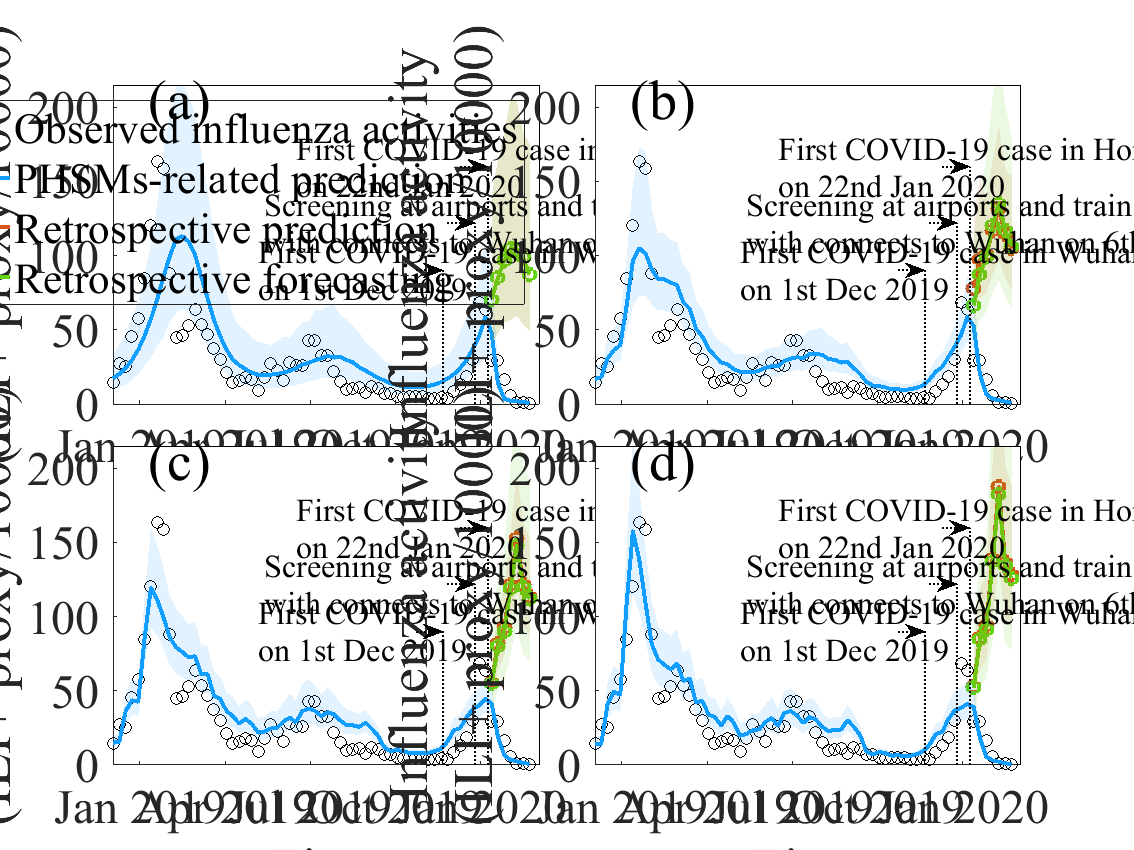

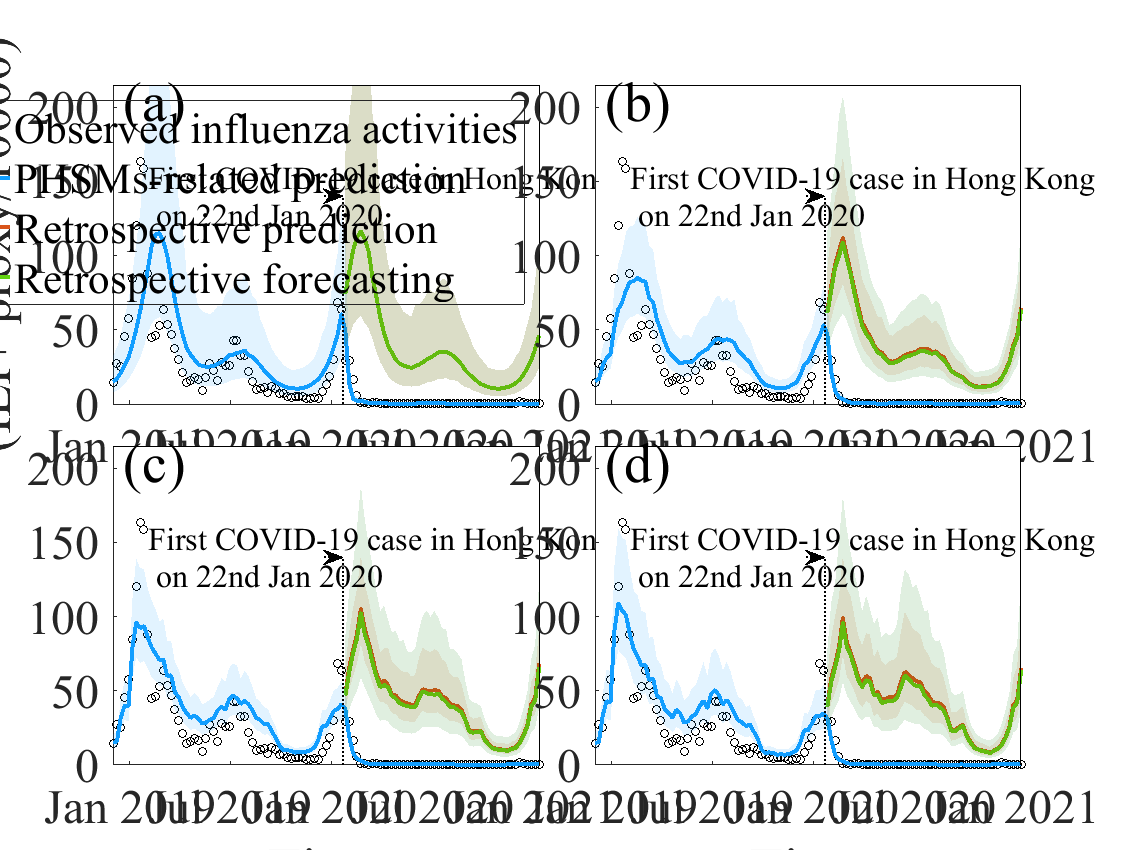

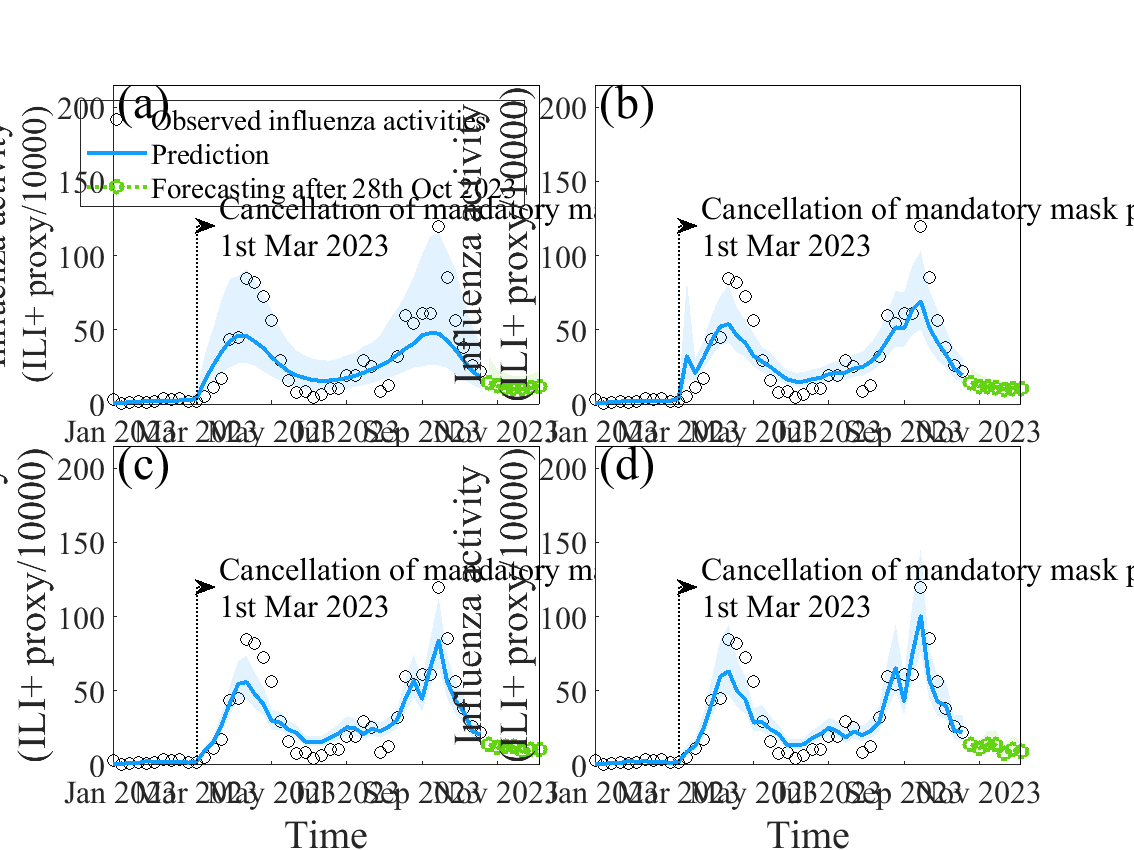

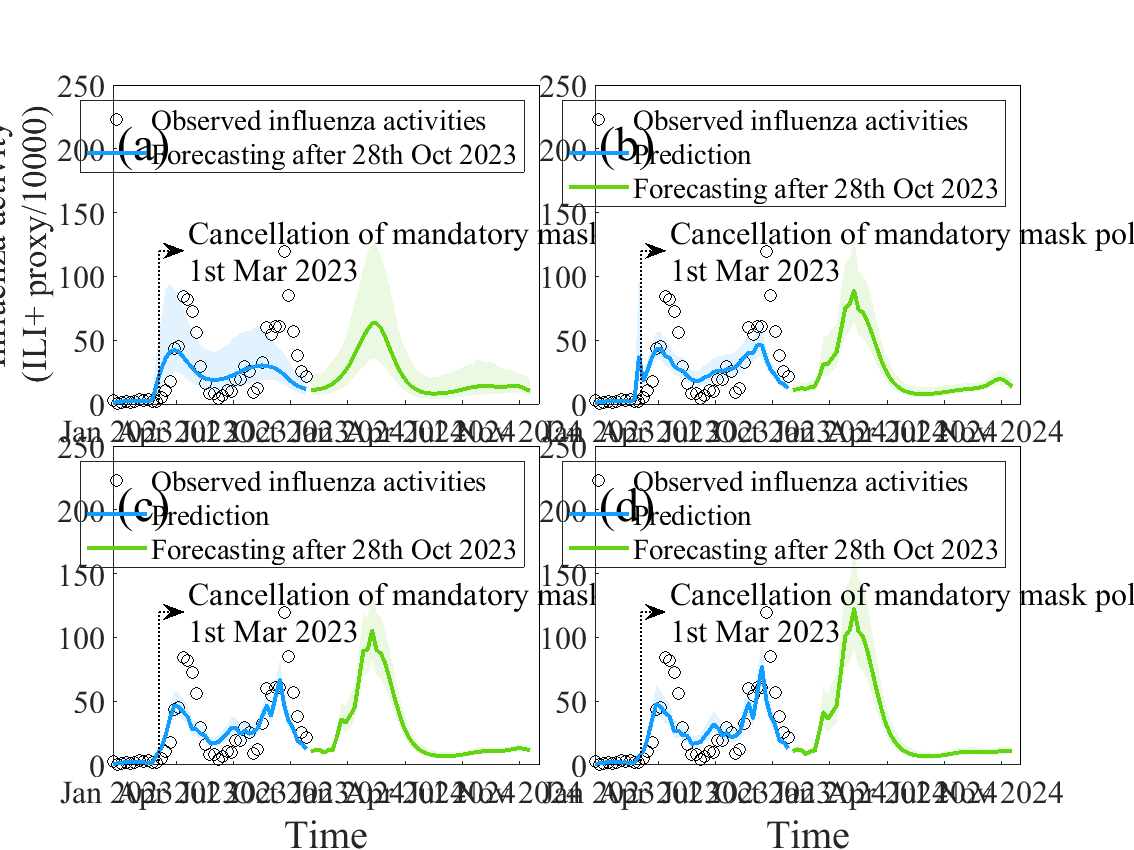

load('ili_proxy_2010_2020.mat')
npistart=525;
Rshort_day = 466:npistart+7; Rshort_day1 = 466:npistart+7; Rshort_day2 = npistart:533; %
Pshort_day1 = 722-52:729; Pshort_day2=671:722;Rshort_day3=526:532;
Rlong_day1 = 466:577;Rlong_day2 = 466:577;Rlong_day3 = 526:577;
PLong_day1 = 671:722;PLong_day2 = 722-52:773;
lims = [0.025,0.5,0.975];%plimshort = plims(R_newPI_short{ENmodel},lims); 
Name = {'(a)','(b)','(c)','(d)','(e)'};

% Rshort_day = npistart:npistart+7; Rshort_day1 = 518:npistart; Rshort_day2 = npistart:533; %
% Pshort_day1 = 722:729; Pshort_day2=688:722;Rshort_day3=526:532;
% Rlong_day1 = 517:577;Rlong_day2 = 525:577;Rlong_day3 = 526:577;
% PLong_day1 = 688:722;PLong_day2 = 722:773;
lims = [0.025,0.5,0.975];%plimshort = plims(R_newPI_short{ENmodel},lims); 
figure();ha1=tight_subplot(2,2,0.05,0.1,0.1);
figure();ha2=tight_subplot(2,2,0.05,0.1,0.1);
figure();ha3=tight_subplot(2,2,0.05,0.1,0.1);
figure();ha4=tight_subplot(2,2,0.05,0.1,0.1);
for ENmodel = 1:4
axes(ha1(ENmodel));hold on;
set(gcf,'unit','centimeters','position',[10 10 20 15]);
set(gca,'FontName','Times New Roman','FontSize',16);
if ENmodel>=3
xlabel('Time','FontName','Times New Roman','FontSize',24);
end
hold on;
set(gcf,'unit','centimeters','position',[10 10 20 15]);
set(gca,'FontName','Times New Roman','FontSize',24);
xlabel('Time');ylabel(sprintf('Influenza activity\n(ILI+ proxy/10000)'));
set(get(gca,'YLabel'),'FontSize',28);
set(get(gca,'XLabel'),'FontSize',28);
set(gca,'xtick',[470.25:4.5*3:575]);xlim([466,533.5])
set(gca,'xticklabel',{'Jan 2019','Apr 2019','Jul 2019','Oct 2019','Jan 2020','Mar 2020'},'XTickLabelRotation',0);ylim([0,215]);
set(gca,'ytick',[0:50:250]);
set(gca,'yticklabel',{'0','50','100','150','200','250'});
 Rlim_short = plims(R_newPI_short{ENmodel},lims);
 Rlim_shortCF = plims(R_newPI_shortCF{ENmodel},lims);
 Rlim_shortCF_F = plims(R_newPI_shortCF_F{ENmodel},lims);

    plot(Rshort_day1,A(Rshort_day1),'o','LineWidth',0.5,'color',[0,0,0]);   
    plot(Rshort_day,Rlim_short(2,1:end),'-','color',[0.07,0.62,1.00],'LineWidth',2);
    plot(Rshort_day3,Rlim_shortCF(2,2:end),'-o','color',[0.85,0.33,0.10],'LineWidth',2);
    plot(Rshort_day3,Rlim_shortCF_F(2,2:end),'-o','color',[0.39,0.83,0.07],'LineWidth',2);

    % plot(525:526,[A(525) Rlim_shortCF_F(2,2)],':','color',[0.39,0.83,0.07],'LineWidth',2); 
    % plot(Rshort_day2,A(Rshort_day2),'o','LineWidth',0.5,'color',[0,0,0]);
    % plot(525:526,[A(525) Rlim_shortCF(2,2)],':','color',[0.85,0.33,0.10],'LineWidth',2);
    % R_newPI_short{ENmodel}(:,1) = A(npistart);%R_newCI_short{ENmodel}(:,1)= A(525);
    % R_newPI_shortCF{ENmodel}(:,1) = A(npistart);
    % R_newPI_shortCF_F{ENmodel}(:,1) = A(npistart);
   
    fillyy(Rshort_day,Rlim_short(1,:),Rlim_short(3,:),[0.07,0.62,1.00],0.12); %obs 95CI
    fillyy(Rshort_day3,Rlim_shortCF(1,2:end),Rlim_shortCF(3,2:end),[0.85,0.33,0.10],0.12); %obs 95CI
    fillyy(Rshort_day3,Rlim_shortCF_F(1,2:end),Rlim_shortCF_F(3,2:end),[0.39,0.83,0.07],0.12); %obs 95CI
    
plot([525.4 525.4],[0 160],':','color',[0 0 0],'LineWidth',1)
text(495,160,sprintf('First COVID-19 case in Hong Kong\non 22nd Jan 2020'),'FontSize',16,'FontName','Times New Roman')
plotarrow(521,525.4, 160,160)
plot([523.4 523.4],[0 122],':','color',[0 0 0],'LineWidth',1)
text(490,122,sprintf('Screening at airports and train stations\nwith connects to Wuhan on 6th Jan 2020'),'FontSize',16,'FontName','Times New Roman')
plotarrow(519,523.4,122,122)
plot([518.3 518.3],[0 90],':','color',[0 0 0],'LineWidth',1)
text(489,90,sprintf('First COVID-19 case in Wuhan\non 1st Dec 2019'),'FontSize',16,'FontName','Times New Roman')
plotarrow(514,518.3, 90,90);box_off;
text(471.5,206,Name(ENmodel),"FontSize",28,'FontName','Times New Roman')
if ENmodel==1
legend('Observed influenza activities','PHSMs-related prediction','Retrospective prediction','Retrospective forecasting','color','none')
end
exportgraphics(gcf,'Figure 1 Short_forecasting_A.pdf','ContentType','vector')


axes(ha2(ENmodel));hold on;
set(gcf,'unit','centimeters','position',[10 10 20 15]);
set(gca,'FontName','Times New Roman','FontSize',24);
xlabel('Time');%ylabel(sprintf('Influenza activity\n(ILI+ proxy/10000)'));
set(get(gca,'YLabel'),'FontSize',28);
set(get(gca,'XLabel'),'FontSize',28);
set(gca,'xtick',[470.3:13*2:577]);
set(gca,'xticklabel',{'Jan 2019','Jul 2019','Jan 2020','Jul 2020','Jan 2021'},'XTickLabelRotation',0);
xlim([466 576]);ylim([0,215]);
set(gca,'ytick',0:50:250);
set(gca,'yticklabel',{'0','50','100','150','200','250'});
Rlim_Long = plims(R_newPI_Long{ENmodel},lims);
Rlim_LongCF = plims(R_newPI_LongCF{ENmodel},lims);
Rlim_LongCF_F = plims(R_newPI_LongCF_F{ENmodel},lims);

plot(Rlong_day1,A(Rlong_day1),'o','MarkerSize',4,'color',[0,0,0]);
plot(Rlong_day2,Rlim_Long(2,1:end),'-','color',[0.07,0.62,1.00],'LineWidth',2);
plot(Rlong_day3,Rlim_LongCF(2,2:end),'-','color',[0.85,0.33,0.10],'LineWidth',2);
plot(Rlong_day3,Rlim_LongCF_F(2,2:end),'-','color',[0.39,0.83,0.07],'LineWidth',2);

fillyy(Rlong_day2,Rlim_Long(1,:),Rlim_Long(3,:),[0.07,0.62,1.00],0.12); %obs 95CI
fillyy(Rlong_day3,Rlim_LongCF(1,2:end),Rlim_LongCF(3,2:end),[0.85,0.33,0.10],0.12); %obs 95CI
fillyy(Rlong_day3,Rlim_LongCF_F(1,2:end),Rlim_LongCF_F(3,2:end),[0 0.5 0],0.12); %obs 95CI

% plot(525:526,[A(525) Rlim_LongCF_F(2,2)],':','color',[0.39,0.83,0.07],'LineWidth',2);
% plot(525:526,[A(525) Rlim_LongCF(2,2)],':','color',[0.85,0.33,0.10],'LineWidth',2);

plot([525.4 525.4],[0 140],':','color',[0 0 0],'LineWidth',1);
text(475,140,sprintf('First COVID-19 case in Hong Kong\n on 22nd Jan 2020'),'FontSize',16,'FontName','Times New Roman');
plotarrow(520.5,525.4,140,140)
text(468.6,205,Name(ENmodel),"FontSize",28,'FontName','Times New Roman')
box_off;

if ENmodel==1
legend('Observed influenza activities','PHSMs-related prediction','Retrospective prediction','Retrospective forecasting','color','none');
ylabel(sprintf('Influenza activity\n(ILI+ proxy/10000)'));
end
% exportgraphics(gcf,'Figure 2 Long_forecasting_A.pdf','ContentType','vector')

%ha=tight_subplot(1,2,0.05,0.1,0.1);%
axes(ha3(ENmodel));hold on;
set(gcf,'unit','centimeters','position',[10 10 20 15]);
set(gca,'FontName','Times New Roman','FontSize',28);
if ENmodel>=3
xlabel('Time','FontName','Times New Roman','FontSize',36);
end 

set(gcf,'unit','centimeters','position',[10 10 20 15]);
set(gca,'FontName','Times New Roman','FontSize',16);
xlabel('Time');ylabel(sprintf('Influenza activity\n(ILI+ proxy/10000)'));
set(get(gca,'YLabel'),'FontSize',20);
set(get(gca,'XLabel'),'FontSize',20);
set(gca,'xtick',[679 688, 697, 706, 715, 724]);
xlim([678 729]);ylim([0,215])
set(gca,'xticklabel',{'Jan 2023','Mar 2023','May 2023','Jul 2023','Sep 2023','Nov 2023'},'XTickLabelRotation',0);
set(gca,'ytick',[0:50:250]);
set(gca,'yticklabel',{'0','50','100','150','200','250'});
Plim_short = plims(P_newPI_short{ENmodel},lims);
plot(Pshort_day2,A(Pshort_day2),'o','LineWidth',0.5,'color',[0 0 0])
plot(Pshort_day1(2:end-7),Plim_short(2,2:end-7),'-','color',[0.07,0.62,1.00],'LineWidth',2);
plot(Pshort_day1(end-6:end),Plim_short(2,end-6:end),':o','color',[0.39,0.83,0.07],'LineWidth',2);

fillyy(Pshort_day1(2:end-7),Plim_short(1,2:end-7),Plim_short(3,2:end-7),[0.07,0.62,1.00],0.12); %obs 95CI
fillyy(Pshort_day1(end-6:end),Plim_short(1,end-6:end),Plim_short(3,end-6:end),[0.39,0.83,0.07],0.12); %obs 95CI

% plot([Pshort_day1(1):Pshort_day1(1)+1],[A(Pshort_day2(end)),Plim_short(2,2)],':','color',[0.39,0.83,0.07],'LineWidth',2);
plot([688.1 688.1],[0 120],':','color',[0 0 0],'LineWidth',1)
text(690.7,120,sprintf('Cancellation of mandatory mask policy on \n1st Mar 2023'),'FontSize',16,'FontName','Times New Roman')
text(678.5,204.5,Name(ENmodel),"FontSize",24,'FontName','Times New Roman')
plotarrow(688.1,690.2,120,120)
box_off
if ENmodel==1
    ylabel(sprintf('Influenza activity\n(ILI+ proxy/10000)'));
legend('Observed influenza activities','Prediction','Forecasting after 28th Oct 2023','color','none')
end
%exportgraphics(gcf,'Figure 5 sen1.pdf','ContentType','vector')

axes(ha4(ENmodel));hold on;
set(gcf,'unit','centimeters','position',[10 10 20 15]);
set(gca,'FontName','Times New Roman','FontSize',24);
if ENmodel>=3
xlabel('Time','FontName','Times New Roman','FontSize',24);
end 

set(gcf,'unit','centimeters','position',[10 10 20 15]);
set(gca,'FontName','Times New Roman','FontSize',16);
xlabel('Time');%ylabel(sprintf('Influenza activity\n(ILI+ proxy/10000)'));
set(get(gca,'YLabel'),'FontSize',20);
set(get(gca,'XLabel'),'FontSize',20);
set(gca,'xtick',[679,[688 701 714 727 740 753 766]+4.5]);
set(gca,'xticklabel',{'Jan 2023','Apr 2023','Jul 2023','Oct 2023','Jan 2024','Apr 2024','Jul 2024','Nov 2024'},'XTickLabelRotation',0);
xlim([678,775]);ylim([0,250]);
set(gca,'ytick',[0:50:250]);
set(gca,'yticklabel',{'0','50','100','150','200','250'});
plot(PLong_day1,A(PLong_day1),'o','LineWidth',0.5,'color',[0 0 0])
Plim_Long = plims(P_newPI_Long{ENmodel},lims);
plot(PLong_day2(2:end-51),Plim_Long(2,2:end-51),'-','color',[0.07,0.62,1.00],'LineWidth',2);
plot(PLong_day2(end-50:end),Plim_Long(2,end-50:end),'-','color',[0.39,0.83,0.07],'LineWidth',2);

fillyy(PLong_day2(2:end-51),Plim_Long(1,2:end-51),Plim_Long(3,2:end-51),[0.07,0.62,1.00],0.12); %obs 95CI
fillyy(PLong_day2(end-50:end),Plim_Long(1,end-50:end),Plim_Long(3,end-50:end),[0.39,0.83,0.07],0.12); %obs 95CI

plot([688.5 688.5],[0 120],':','color',[0 0 0],'LineWidth',1)
text(695,120,sprintf('Cancellation of mandatory mask policy on \n1st Mar 2023'),'FontSize',16,'FontName','Times New Roman')
plotarrow(688.5,694,120,120)
text(679,204.5,Name(ENmodel),"FontSize",24,'FontName','Times New Roman');box_off
legend('Observed influenza activities','Prediction','Forecasting after 28th Oct 2023','color','none')

if ENmodel==1
        ylabel(sprintf('Influenza activity\n(ILI+ proxy/10000)'));
legend('Observed influenza activities','Forecasting after 28th Oct 2023','color','none')
end
%exportgraphics(gcf,'Figure 5 sen2.pdf','ContentType','vector')
end